# Self organising map 

Erik Norlin    

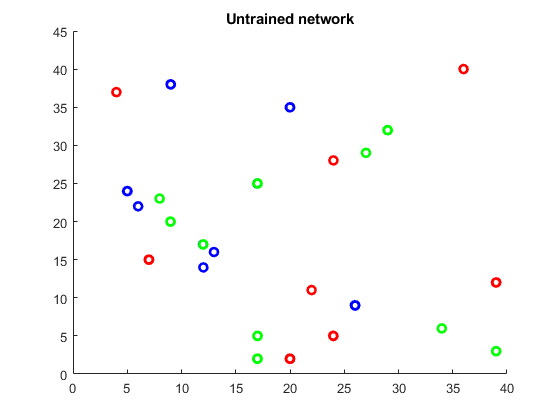

data = readmatrix("iris-data.csv");
targets = readmatrix("iris-labels.csv");
maxValue = max(max(data));
data = data / maxValue;
nInputs = height(data);
nEpochs = 10;

eta_0 = 1;
eta_decay = 0.01;

sigma_0 = 10;
sigma_decay = 0.05;

w_ij = rand(40,40,4);
nNeurons = 40;

% Plotting untrained network
r_0List = [];
class0 = [];
class1 = [];
class2 = [];
for iInput = 1:nInputs
    dataPoint = data(iInput,:);
    minDistance = Inf;      
    
    % Computing the winning neuron
    for i = 1:nNeurons
        for j = 1:nNeurons
            distance = sqrt((w_ij(i,j,1) - dataPoint(1))^2 + ...
                            (w_ij(i,j,2) - dataPoint(2))^2 + ...
                            (w_ij(i,j,3) - dataPoint(3))^2 + ...
                            (w_ij(i,j,4) - dataPoint(4))^2);
            
            if distance < minDistance
                minDistance = distance;
                r_0 = [i+((2*rand)-1)*0.02,j+((2*rand)-1)*0.02];
            end
        end
    end
    
    r_0List = [r_0List ; r_0,targets(iInput)];
    
    if r_0List(iInput,3) == 0
        class0 = [class0 ; r_0List(iInput,:)];
    elseif r_0List(iInput,3) == 1
        class1 = [class1 ; r_0List(iInput,:)];
    elseif r_0List(iInput,3) == 2
        class2 = [class2 ; r_0List(iInput,:)];
    end
end

figure
hold on
plot(class0(:,1),class0(:,2),"or","Linewidth",2)
plot(class1(:,1),class1(:,2),"ob","Linewidth",2)
plot(class2(:,1),class2(:,2),"og","Linewidth",2)
title("Untrained network")
hold off

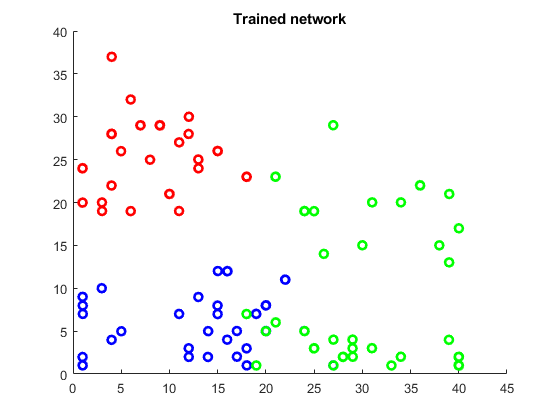


% Training
for iEpoch = 1:nEpochs
    
    % Updating learning parameters
    eta = eta_0*exp(-eta_decay*iEpoch);
    sigma = sigma_0*exp(-sigma_decay*iEpoch);
    
    for iInput = nInputs
        
        randPoint = randi(nInputs);
        dataPoint = data(randPoint,:);
        minDistance = Inf;
        r = [];
        
        % Computing the winning neuron
        for i = 1:nNeurons
            for j = 1:nNeurons
                distance = sqrt((w_ij(i,j,1) - dataPoint(1))^2 + ...
                                (w_ij(i,j,2) - dataPoint(2))^2 + ...
                                (w_ij(i,j,3) - dataPoint(3))^2 + ...
                                (w_ij(i,j,4) - dataPoint(4))^2);
                
                if distance < minDistance
                    minDistance = distance;
                    iMin = i;
                    jMin = j;
                end
            end
        end
        
        % Computing nearest neighbours to the winning neuron
        for i = 1:nNeurons
            for j = 1:nNeurons
                distance = sqrt((i - iMin)^2 + (j - jMin)^2);
                if distance < 3*sigma
                    r = [r ; i,j,distance];
                end
            end
        end
          
        % Updating weights
        nIncrements = height(r);
        deltaWeight = zeros(40,40,4);
        for iIncrement = 1:nIncrements
            i = r(iIncrement,1);
            j = r(iIncrement,2);
            rDistance = r(iIncrement,3);
            
            h = exp(-1/(2*sigma^2) * rDistance^2);
            for k = 1:length(dataPoint)
                deltaWeight(i,j,k) = deltaWeight(i,j,k) + eta*h*(dataPoint(k) - w_ij(i,j,k));
            end
        end
        w_ij = w_ij + deltaWeight;
    end
end

% Plotting trained network
r_0List = [];
class0 = [];
class1 = [];
class2 = [];
for iInput = 1:nInputs
    dataPoint = data(iInput,:);
    minDistance = Inf;      
    
    % Computing the winning neuron
    for i = 1:nNeurons
        for j = 1:nNeurons
            distance = sqrt((w_ij(i,j,1) - dataPoint(1))^2 + ...
                            (w_ij(i,j,2) - dataPoint(2))^2 + ...
                            (w_ij(i,j,3) - dataPoint(3))^2 + ...
                            (w_ij(i,j,4) - dataPoint(4))^2);
            
            if distance < minDistance
                minDistance = distance;
                r_0 = [i+((2*rand)-1)*0.02  ,j+((2*rand)-1)*0.02];
            end
        end
    end
    
    r_0List = [r_0List ; r_0,targets(iInput)];
    
    if r_0List(iInput,3) == 0
        class0 = [class0 ; r_0List(iInput,:)];
    elseif r_0List(iInput,3) == 1
        class1 = [class1 ; r_0List(iInput,:)];
    elseif r_0List(iInput,3) == 2
        class2 = [class2 ; r_0List(iInput,:)];
    end
end

figure
hold on
plot(class0(:,1),class0(:,2),"or","Linewidth",2)
plot(class1(:,1),class1(:,2),"ob","Linewidth",2)
plot(class2(:,1),class2(:,2),"og","Linewidth",2)
title("Trained network")
hold off